clear
h_bar = 6.582e-16;
a = 5.6532e-10;

## **1)**

% Plot the resulting band structure
k_x_min = -0.1*2*pi/a;
k_x_max = 0.1*2*pi/a;
n_points = 100;
k_x_mesh = linspace(k_x_min, k_x_max, n_points)*a/(2*pi);

bands = band_structure(k_x_min, k_x_max, n_points, true, false);
gap = bands(n_points/2, 8) - bands(n_points/2, 6)

gap = 1.4241

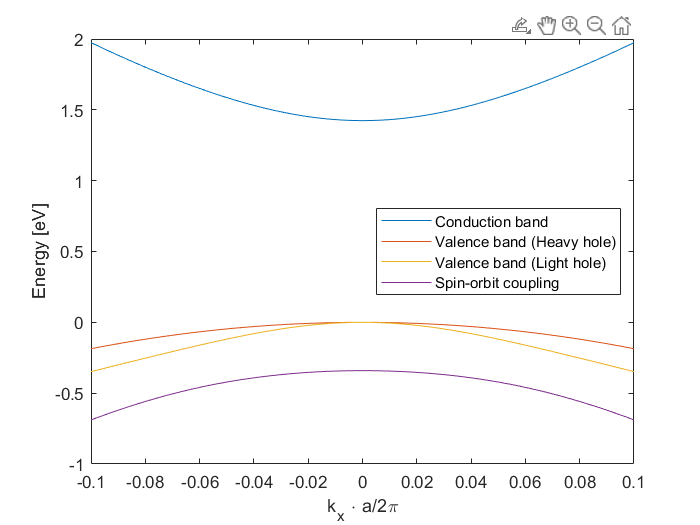


% Plot results
plot(k_x_mesh, bands(:, 8:-2:1))
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');
%xlim([k_x_min, k_x_max]);
legend('Conduction band', 'Valence band (Heavy hole)', 'Valence band (Light hole)', 'Spin-orbit coupling', 'Location', 'east');

## 2)

valence_heavy_coeff  = polyfit(k_x_mesh, bands(:, 6), 2) * (a / (2*pi))^2;
valence_light_coeff  = polyfit(k_x_mesh, bands(:, 4), 2) * (a / (2*pi))^2;

d2_heavy = 2*valence_heavy_coeff(1);
d2_light = 2*valence_light_coeff(1);

mass_heavy = h_bar^2 / d2_heavy 

mass_heavy = -1.4375e-12

mass_light = h_bar^2 / d2_light

mass_light = -7.4375e-13

mass_heavy/mass_light

ans = 1.9328

## 3)

bands_without_so = band_structure(k_x_min, k_x_max, n_points, false, false);
gap_without_so = bands_without_so(n_points/2, 8) - bands_without_so(n_points/2, 6)

gap_without_so = 1.5378

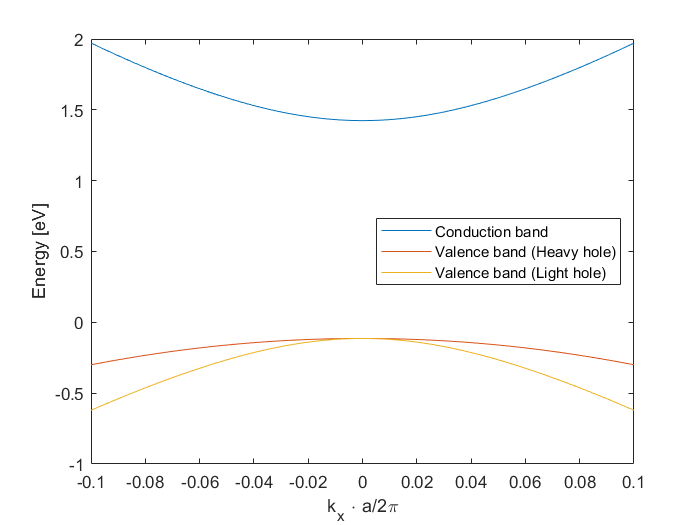


% Plot results
figure
plot(k_x_mesh, bands_without_so(:, [8, 6, 2]))
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');
legend('Conduction band', 'Valence band (Heavy hole)', 'Valence band (Light hole)', 'Location', 'east');


% Calculate effective masses of valence band holes w.o. spin-orbit
valence_upper_coeff  = polyfit(k_x_mesh, bands_without_so(:, 4), 2) * (a / (2*pi))^2;
valence_lower_coeff  = polyfit(k_x_mesh, bands_without_so(:, 2), 2) * (a / (2*pi))^2;

d2_upper = 2*valence_upper_coeff(1);
d2_lower = 2*valence_lower_coeff(1);

mass_heavy = h_bar^2 / d2_upper 

mass_heavy = -1.4375e-12

mass_light = h_bar^2 / d2_lower

mass_light = -5.1746e-13

mass_heavy/mass_light

ans = 2.7780

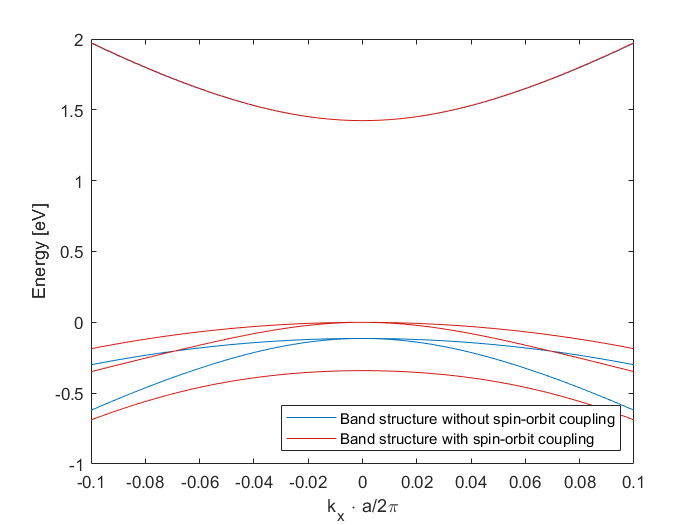


% Compare band strucres
figure
plot(k_x_mesh, bands_without_so(:, 2:2:8), "Color", "#0072BD")
hold on
plot(k_x_mesh, bands(:, 2:2:8), "Color", "#d11e15")
legend("Band structure without spin-orbit coupling", "", "", "", "", "Band structure with spin-orbit coupling", "Location", "southeast")
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');

## 4)

bands_with_strain = band_structure(k_x_min, k_x_max, n_points, true, true);
bands_with_strain_without_so = band_structure(k_x_min, k_x_max, n_points, false, true);
gap_with_strain = bands_with_strain(n_points/2, 8) - bands_with_strain(n_points/2, 6)

gap_with_strain = 0.9241

gap_with_strain_without_so = bands_with_strain_without_so(n_points/2, 8) - bands_with_strain_without_so(n_points/2, 6)

gap_with_strain_without_so = 1.0378

With spin-orbit

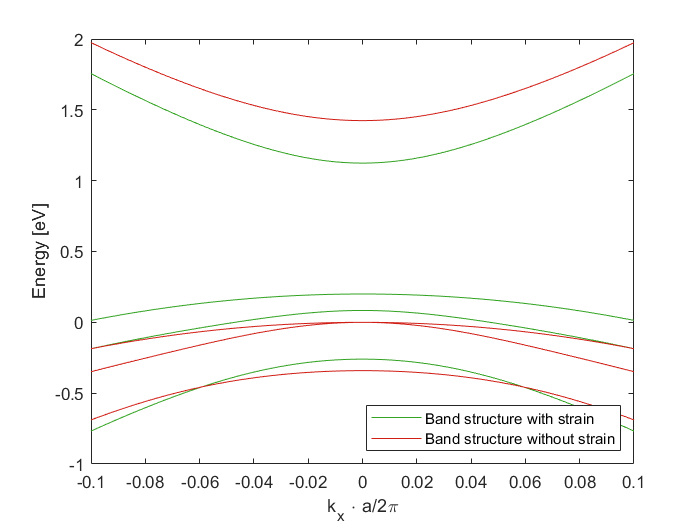

% Plot results
figure
plot(k_x_mesh, bands_with_strain(:, 8:-2:2), "Color", "#33a322")
hold on
plot(k_x_mesh, bands, "Color", "#d11e15")
legend("Band structure with strain", "", "", "", "", "Band structure without strain", "Location", "southeast")
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');

Without spin-orbit

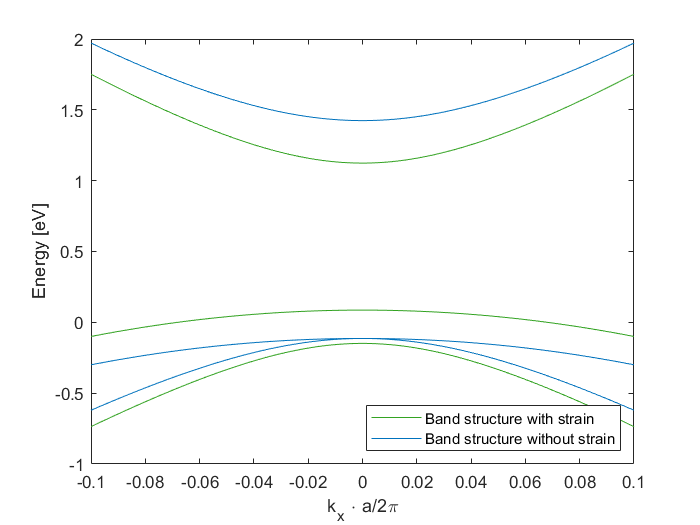

% Plot results
figure
plot(k_x_mesh, bands_with_strain_without_so(:, 8:-2:2), "Color", "#33a322")
hold on
plot(k_x_mesh, bands_without_so, "Color", "#0072BD")
legend("Band structure with strain ", "", "", "", "", "Band structure without strain", "Location", "southeast")
xlabel('k_x \cdot a/2\pi');
ylabel('Energy [eV]');